% Name: Redwan-Ul-Bari
% ID: 190021119
% Section: A
% Part 1: Modeling the OCC

clc 
clear all

### **Open Circuit Characteristics**

I=0.25:0.25:1.5

I =     0.2500    0.5000    0.7500    1.0000    1.2500    1.5000


E=[60,120,180,210,225,230]

E =     60   120   180   210   225   230



t=table(I',E','VariableNames',{'Field Current(if) (A)','Generated Voltage(Eg) (V)'})

t = 6×2 table
    Field Current(if) (A)    Generated Voltage(Eg) (V)
    _____________________    _________________________

            0.25                         60           
             0.5                        120           
            0.75                        180           
               1                        210           
            1.25                        225           
             1.5                        230           


#### Linearization of saturation-growth-rate equation

close all
c=1./I

c =     4.0000    2.0000    1.3333    1.0000    0.8000    0.6667


e=1./E

e =     0.0167    0.0083    0.0056    0.0048    0.0044    0.0043


n=1

n = 1

I_s=zeros(n+1);
for i=1:(n+1)
    for j=1:(n+1)
    I_s(i,j)=(sum(c.^((i+j)-2)));
    end
end

E_s=zeros(n+1,1);
for i=1:(n+1)
    E_s(i,1)=(sum((c.^(i-1)).*e));
end
I_s

I_s =     6.0000    9.8000
    9.8000   23.8622


E_s

E_s =     0.0441
    0.1020


A=pinv(I_s)*E_s

A =     0.0011
    0.0038



Alpha=1/A(1,1)

Alpha = 882.9769

Beta=A(2,1)*Alpha

Beta = 3.3620


plot(I,E,'o') 
hold on;

y=(Alpha.*I)./(Beta+I)

y =    61.1137  114.3152  161.0477  202.4235  239.3136  272.4101


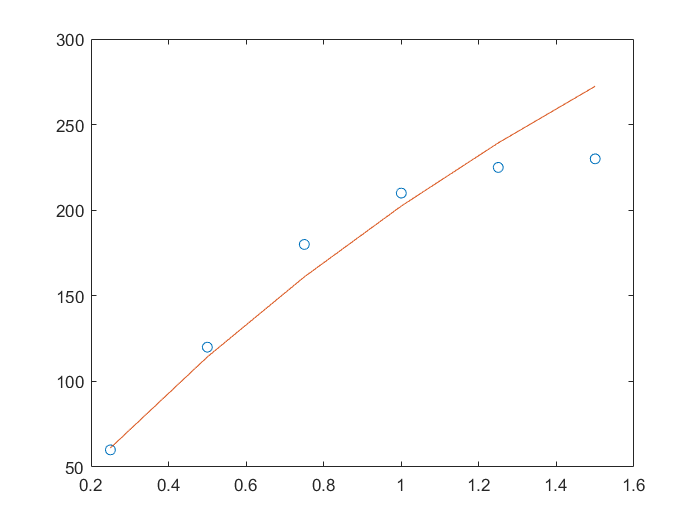

plot(I,y)


Sr=sum((E-y).^2)

Sr = 2.4536e+03

St=sum((E-mean(E)).^2)

St = 2.2921e+04

r_squared=(St-Sr)/St

r_squared = 0.8930


fprintf("Goodness of fit is %f percent",r_squared*100)

Goodness of fit is 89.295137 percent

#### **Fitting 2nd order **polynomial

close all
n=2

n = 2

I_s=zeros(n+1);
for i=1:(n+1)
    for j=1:(n+1)
    I_s(i,j)=(sum(I.^((i+j)-2)));
    end
end

E_s=zeros(n+1,1);
for i=1:(n+1)
    E_s(i,1)=(sum((I.^(i-1)).*E));
end
I_s

I_s =     6.0000    5.2500    5.6875
    5.2500    5.6875    6.8906
    5.6875    6.8906    8.8867


E_s

E_s = 	1.0e+03 *

    1.0250
    1.0462
    1.2141


A1=pinv(I_s)*E_s

A1 =   -24.5000
  364.0714
 -130.0000



plot(I,E,'o') 
hold on;
E_p=zeros(n+1,6);
for i=1:(n+1)
        E_p(i,:)=A1(i,1)*I.^(i-1);
end
Y=sum(E_p)

Y =    58.3929  125.0357  175.4286  209.5714  227.4643  229.1071


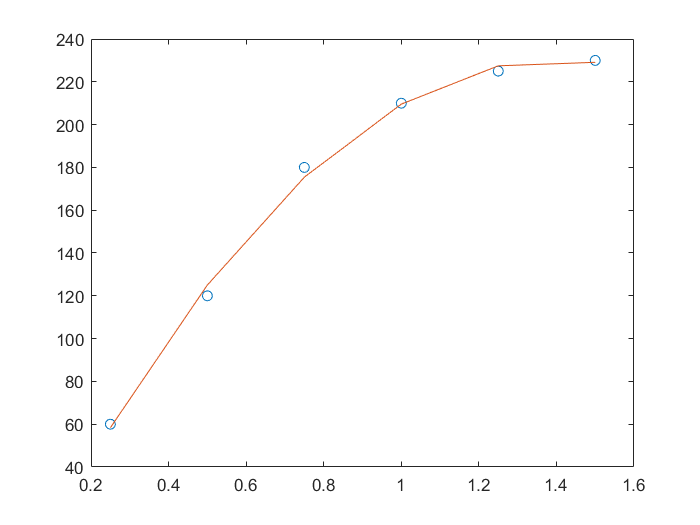

plot(I,Y)

Sr=sum((E-Y).^2)

Sr = 55.8929

St=sum((E-mean(E)).^2)

St = 2.2921e+04

r_squared1=(St-Sr)/St

r_squared1 = 0.9976


fprintf("Goodness of fit is %f percent",r_squared1*100)

Goodness of fit is 99.756148 percent

#### **Fitting 3rd order **polynomial 

close all
n=3

n = 3

I_s=zeros(n+1);
for i=1:(n+1)
    for j=1:(n+1)
    I_s(i,j)=(sum(I.^((i+j)-2)));
    end
end

E_s=zeros(n+1,1);
for i=1:(n+1)
    E_s(i,1)=(sum((I.^(i-1)).*E));
end
I_s

I_s =     6.0000    5.2500    5.6875    6.8906
    5.2500    5.6875    6.8906    8.8867
    5.6875    6.8906    8.8867   11.9150
    6.8906    8.8867   11.9150   16.3992


E_s

E_s = 	1.0e+03 *

    1.0250
    1.0462
    1.2141
    1.5176


A2=pinv(I_s)*E_s

A2 =   -23.3333
  358.2011
 -122.2222
   -2.9630



plot(I,E,'x') 
hold on;
E_p=zeros(n+1,6);
for i=1:(n+1)
        E_p(i,:)=A2(i,1)*I.^(i-1);
end
Y=sum(E_p)

Y =    58.5317  124.8413  175.3175  209.6825  227.6587  228.9683


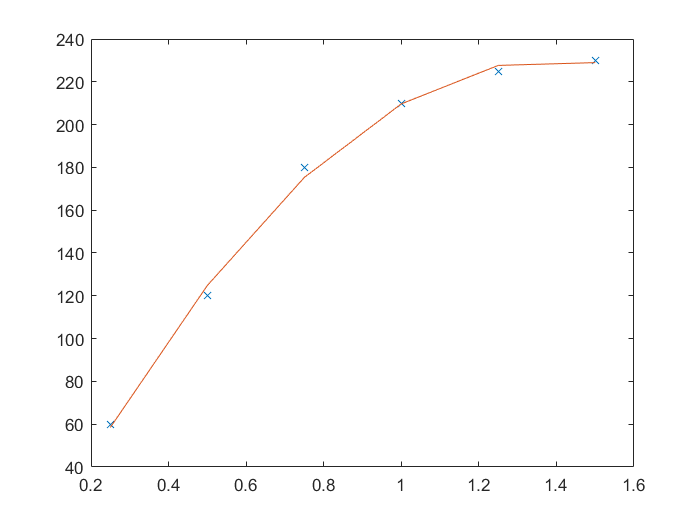

plot(I,Y)



Sr=sum((E-Y).^2)

Sr = 55.7540

St=sum((E-mean(E)).^2)

St = 2.2921e+04

r_squared2=(St-Sr)/St

r_squared2 = 0.9976


fprintf("Goodness of fit is %f percent",r_squared2*100)

Goodness of fit is 99.756754 percent

#### **Fitting 4th order **polynomial 

close all
n=4

n = 4

I_s=zeros(n+1);
for i=1:(n+1)
    for j=1:(n+1)
    I_s(i,j)=(sum(I.^((i+j)-2)));
    end
end

E_s=zeros(n+1,1);
for i=1:(n+1)
    E_s(i,1)=(sum((I.^(i-1)).*E));
end
I_s

I_s =     6.0000    5.2500    5.6875    6.8906    8.8867
    5.2500    5.6875    6.8906    8.8867   11.9150
    5.6875    6.8906    8.8867   11.9150   16.3992
    6.8906    8.8867   11.9150   16.3992   22.9957
    8.8867   11.9150   16.3992   22.9957   32.6934


E_s

E_s = 	1.0e+03 *

    1.0250
    1.0462
    1.2141
    1.5176
    1.9884


A3=pinv(I_s)*E_s

A3 =    29.1667
   -3.4656
  656.1111
 -656.2963
  186.6667



plot(I,E,'*') 
hold on;
E_p=zeros(n+1,6);
for i=1:(n+1)
        E_p(i,:)=A3(i,1)*I.^(i-1);
end
Y=sum(E_p)

Y =    59.7817  121.0913  177.8175  212.1825  223.9087  230.2183


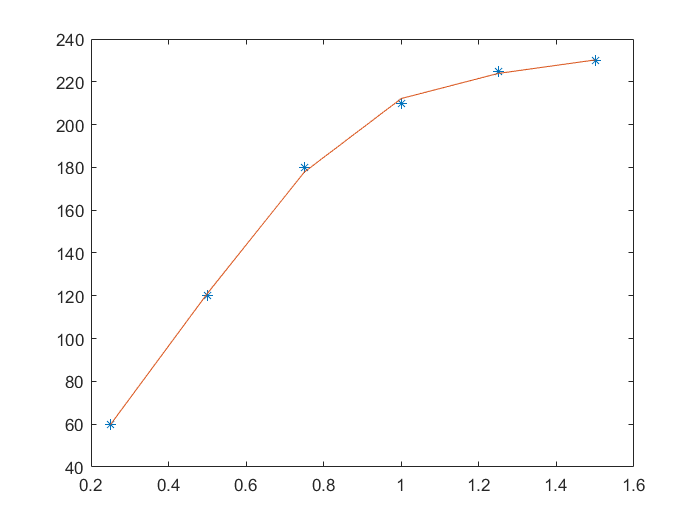

plot(I,Y)



Sr=sum((E-Y).^2)

Sr = 12.0040

St=sum((E-mean(E)).^2)

St = 2.2921e+04

r_squared3=(St-Sr)/St

r_squared3 = 0.9995


fprintf("Goodness of fit is %f percent",r_squared3*100)

Goodness of fit is 99.947629 percent

rstable= table(r_squared*100,r_squared1*100,r_squared2*100,r_squared3*100,'VariableNames',{'Linearization of saturation-growth-rate equation','2nd order polynomial','3rd order polynomial','4th order polynomial'})

rstable = 1×4 table
    Linearization of saturation-growth-rate equation    2nd order polynomial    3rd order polynomial    4th order polynomial
    ________________________________________________    ____________________    ____________________    ____________________

                         89.295                                99.756                  99.757                  99.948       
